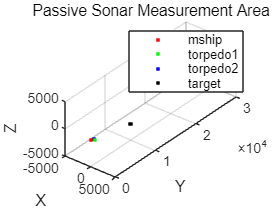

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

clc; clear; close all;

%% Sensor / Target initialize

% 패시브 소나와 EKF를 이용한 방위각 기반 타겟 위치 추정 알고리즘
% 두개의 어뢰와 모선에 있는 소나 센서를 이용
% State=[x y z vx vy vz]'
% measurement=[b e]'각각 방위각, 양각 
% 필터 :  EKF
load("m_10.mat")% trajectory 파일들은 따로 생성 후 관리. 이 파일 안에 trajectories.target 형태로 저장.
% 새로 만들거나 수정할 때는 그냥 matlab에서 trajectories.target=[0 0 0; 1 1 1; ...] 이렇게 추가하면됨
target=initializeTarget([90 -20],15,DOPgoodtrajectories1.target); % [azimuth elevation](deg) velocity trajectory

%% Mothership and Torpedoes initialization
mship=initializeSensor(20,10000,1,target,DOPgoodtrajectories1.mship);%v,maxD,noise(deg),target,trajectory
torpedo1=initializeSensor(20,10000,1,target,DOPgoodtrajectories1.torpedo1);%v,maxD,noise(deg),target,trajectory
torpedo2=initializeSensor(20,10000,1,target,DOPgoodtrajectories1.torpedo2);%v,maxD,noise(deg),target,trajectory

%% Uncertainty Area Calculation
th=800;%threshold for combining

%% Visualization
figure; hold on;
plot3(mship.Pos(1), mship.Pos(2), mship.Pos(3),'r.');
plot3(torpedo1.Pos(1), torpedo1.Pos(2), torpedo1.Pos(3),'g.');
plot3(torpedo2.Pos(1), torpedo2.Pos(2), torpedo2.Pos(3), 'b.');
plot3(target.Pos(1), target.Pos(2), target.Pos(3), 'k.');

title('Passive Sonar Measurement Area');
xlabel('X'); ylabel('Y'); zlabel('Z');
legend('mship', 'torpedo1', 'torpedo2','target');
axis equal;

xlim([-5000 5000]);
ylim([0 30000]);
zlim([-5000 5000]);

grid on;
view([40 -50 40]);
%% EKF Tracking

%% Simulation
condition=zeros(length(target.traj),1);
for i=1:1:length(target.traj)
    %visualization
    plot3(mship.Pos(1), mship.Pos(2), mship.Pos(3),'r.');
    plot3(torpedo1.Pos(1), torpedo1.Pos(2), torpedo1.Pos(3),'g.');
    plot3(torpedo2.Pos(1), torpedo2.Pos(2), torpedo2.Pos(3), 'b.');
    plot3(target.Pos(1), target.Pos(2), target.Pos(3), 'k.');
    legend('mship', 'torpedo1', 'torpedo2','target');

    %sonar sensor measuring
    mship.sonar = updateSensor(10000, 1, mship.State(1:3), mship.heading);
    torpedo1.sonar = updateSensor(10000, 1, torpedo1.State(1:3), torpedo1.heading);
    torpedo2.sonar = updateSensor(10000, 1, torpedo2.State(1:3), torpedo2.heading);
    
    %extract uncertainarea of sonar sensors
    [uncertainArea, eigenVect, eigenVal, condNum] = findUncertaintyArea(mship.sonar, torpedo1.sonar, torpedo2.sonar, th);
    condition(i)=condNum;

    i%counting progress

    %model state update
    target=updateSimulation(target);
    mship=updateSimulation(mship);
    torpedo1=updateSimulation(torpedo1);
    torpedo2=updateSimulation(torpedo2);
    drawnow;
end

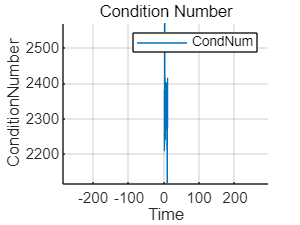

%% Visualization
figure; hold on;
plot([1:length(condition)],condition)
title('Condition Number');
xlabel('Time'); ylabel('ConditionNumber');
legend('CondNum');
axis equal;
grid on;
hold off;


%% Functions

% Update Sensor Function
function sonar = updateSensor(maxDistance, noise, position, heading)
    sonar.maxD = maxDistance; % 최대 측정 거리
    sonar.noise = deg2rad(noise); % 각 센서의 measurement Noise (angle)
    sonar.maxR = tan(sonar.noise) * sonar.maxD; % noise 기반 원뿔 반지름 생성
    sonar.numPoints = 1000; % 포인트 수

    sonar.P = position'; % 센서 위치
    sonar.D = [cos(heading(2)) * cos(heading(1)), ...
               cos(heading(2)) * sin(heading(1)), ...
               sin(heading(2))]; % 헤딩 방향은 방위각과 양각 기반으로 생성

    % 랜덤 포인트 생성
    theta1 = 2 * pi * rand(sonar.numPoints, 1);
    z1 = sonar.maxD * rand(sonar.numPoints, 1);
    r1 = sqrt(rand(sonar.numPoints, 1)) .* (z1 / sonar.maxD) * sonar.maxR;
    x1 = r1 .* cos(theta1);
    y1 = r1 .* sin(theta1);

    % 좌표 변환 (회전 및 병진 변환 적용)
    sonar.points = [x1, y1, z1];
    zAxis = [0, 0, 1];
    v = cross(zAxis, sonar.D);
    s = norm(v);
    c = dot(zAxis, sonar.D);
    vx = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
    R = eye(3) + vx + vx^2 * ((1 - c) / s^2);
    sonar.points = (R * sonar.points')' + sonar.P;
end

% Find Uncertainty Area Function
function [uncertainty, eigenVect, eigenVal, condNum] = findUncertaintyArea(sensor1, sensor2, sensor3, th)
    % sensor1, sensor2, sensor3: 구조체, 각각 points (Point Cloud), P (위치), D (방향) 등 포함
    % th: 거리 임계값 (겹치는 영역 기준)
    % uncertainty: 세 UUV의 겹치는 영역 (공통 포인트)

    % Step 1: Sensor 1과 Sensor 2 간의 겹치는 영역 계산
    distances12 = pdist2(sensor1.points, sensor2.points);
    [UUV1_matchIdx_12, ~] = find(distances12 < th);
    overlap12 = sensor1.points(UUV1_matchIdx_12, :);

    % Step 2: Sensor 3과 overlap12의 겹치는 영역 계산
    distances123 = pdist2(overlap12, sensor3.points);
    [overlap12_matchIdx, ~] = find(distances123 < th);
    uncertainty = overlap12(overlap12_matchIdx, :);

    % 공분산 행렬 계산
    covMat = cov(uncertainty);

    % 고유 값 및 고유 벡터 계산
    [eigenVect, eigenVal] = eig(covMat);

    % 컨디션 넘버 계산
    condNum = cond(covMat);
end

%모델 초기화
function target=initializeTarget(heading,v,trajectory)
    target.vel = v; % 속력
    target.heading = [deg2rad(heading(1)) deg2rad(heading(2))]; % 헤딩각
    target.Pos = trajectory(1,:);
    target.PosIdx=1;
    target.State = [target.Pos, ...
    target.vel * cos(target.heading(2)) * cos(target.heading(1)), ...
    target.vel * cos(target.heading(2)) * sin(target.heading(1)), ...
    target.vel * sin(target.heading(2))]'; % 상태 변수
    target.traj=trajectory;
end

function tracker=initializeSensor(v,maxD,noise,target,trajectory)
    tracker.vel = v;
    tracker.Pos = trajectory(1,:);
    tracker.PosIdx=1;
    tracker.heading = [atan2(target.Pos(2) - tracker.Pos(2), target.Pos(1) - tracker.Pos(1)), ...
        atan2(target.Pos(3) - tracker.Pos(3), norm(target.Pos(1:2) - tracker.Pos(1:2)))];
    tracker.State = [tracker.Pos, ...
        tracker.vel * cos(tracker.heading(2)) * cos(tracker.heading(1)), ...
        tracker.vel * cos(tracker.heading(2)) * sin(tracker.heading(1)), ...
        tracker.vel * sin(tracker.heading(2))]';
    % 센서 업데이트 (원뿔 생성)
    tracker.sonar = updateSensor(maxD, noise, tracker.State(1:3), tracker.heading);
    tracker.traj=trajectory;
end
function model=updateSimulation(model)
    model.PosIdx=model.PosIdx+1;
    if model.PosIdx<=length(model.traj)
        model.Pos=model.traj(model.PosIdx,:);
    end
end